# Project: GDP regression

## Explanatory analysis

### Descriptive statistics

file = 'data/taiwan.csv'

file = 'data/taiwan.csv'

data = readtable(file);
format compact
%fun  = @(x) log(x);
%data = varfun(fun,data);
t =  data.Properties.VariableNames;
stats = describe(data);
%writetable(stats,'summary_stats_china.csv')

Histogram plots

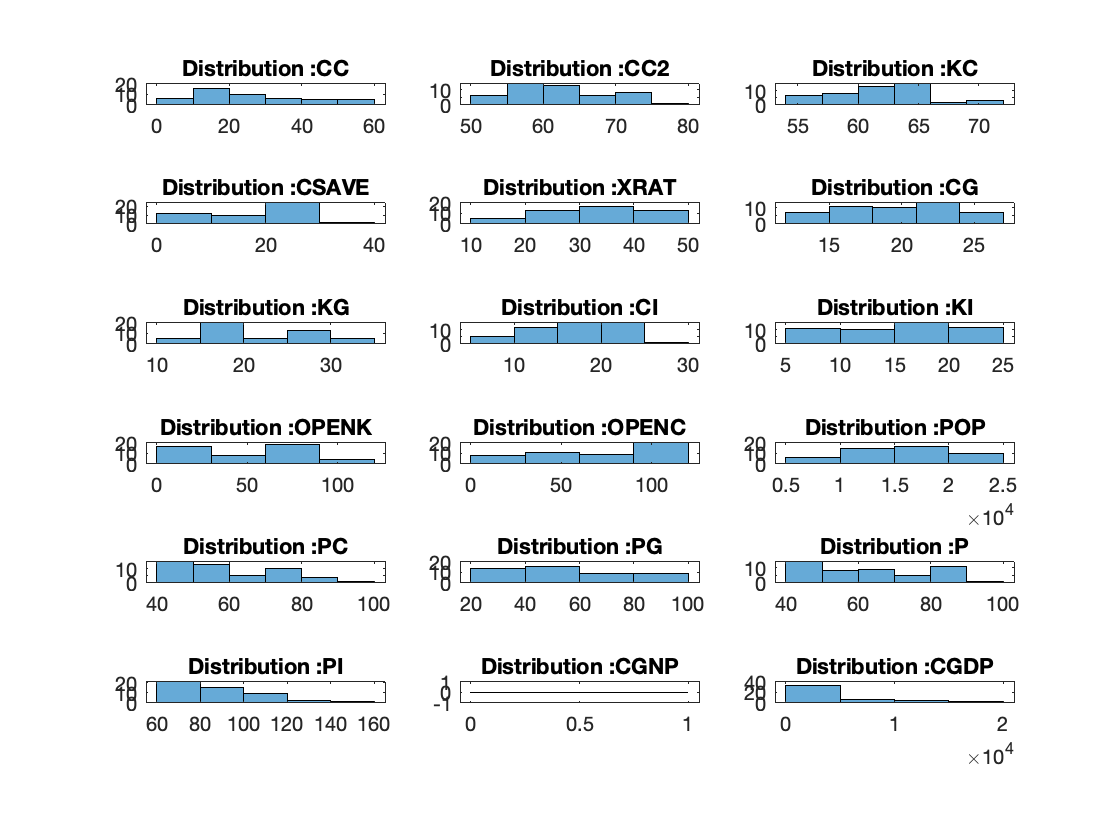

figure
for col = 2:size(data,2)
    subplot(6,3,col-1)
    histogram(data.(col))
    %set(gca,'YScale','log')
    %set(gca,'XScale','log')
    title(strcat('Distribution :',data.Properties.VariableNames{col}))
end

Correlation analysis

matrix = preprocess(file);
corr = corrcoef(matrix(:,2:end));
figure
h = heatmap(corr,"Colormap",flipud(colormap('parula')))

h =   HeatmapChart with properties:

        XData: {18×1 cell}
        YData: {18×1 cell}
    ColorData: [18×18 double]

  Show all properties

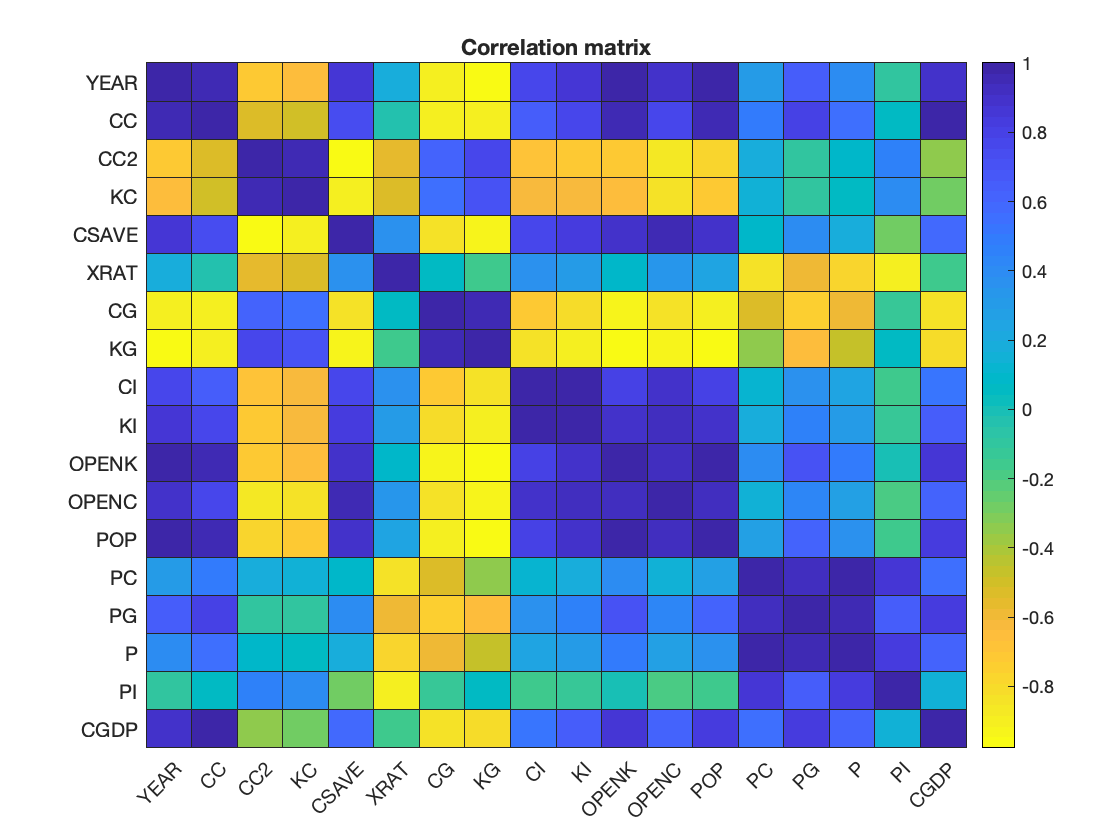

h.Title  = 'Correlation matrix';
feature_names = ["YEAR","CC","CC2","KC","CSAVE","XRAT","CG","KG","CI","KI","OPENK","OPENC","POP","PC","PG","P","PI","CGDP"];
h.XDisplayLabels = feature_names;
h.YDisplayLabels = feature_names;


% data seems colinear => test condition number (without GDP)
X = matrix(:,1:end-1)

X = 	1.0e+04 *

    0.0001    0.1951    0.0008    0.0073    0.0067    0.0004    0.0010    0.0022    0.0030    0.0009    0.0007    0.0015    0.0025    0.8255    0.0079    0.0064    0.0080    0.0130
    0.0001    0.1952    0.0009    0.0074    0.0069    0.0004    0.0010    0.0021    0.0029    0.0010    0.0008    0.0017    0.0022    0.8541    0.0096    0.0077    0.0096    0.0144
    0.0001    0.1953    0.0009    0.0074    0.0069    0.0006    0.0016    0.0020    0.0028    0.0011    0.0009    0.0017    0.0022    0.8822    0.0078    0.0058    0.0076    0.0098
    0.0001    0.1954    0.0010    0.0076    0.0069    0.0003    0.0016    0.0022    0.0029    0.0011    0.0009    0.0015    0.0021    0.9134    0.0076    0.0065    0.0077    0.0113
    0.0001    0.1955    0.0010    0.0073    0.0068    0.0004    0.0016    0.0023    0.0029    0.0009    0.0007    0.0013    0.0021    0.9480    0.0082    0.0070    0.0083    0.0130
    0.0001    0.1956    0.0010    0.0072    0.0065    0.0003    0.0025    0.002

%[condition_nb,~,~] = colinearity_analysis(X)

### scatter plot for between each feature and GDP

%figure
for col = 1:size(data,2)-1
    %subplot(6,3,col)
    %scatter(data.(col),data.CGDP)
    %xlabel(data.Properties.VariableNames{col})
    %ylabel('CGDP')
end